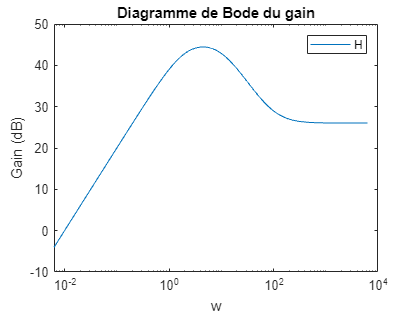

f = 0 : 0.001 : 1000;
w = 2*pi*f;
S = 1i*w;
H = (20*S.*(S+100)) ./ ((S+2).*(S+10));
module = 20*log10(abs(H));
phase = angle(H);

figure('name', 'Diagramme de Bode du gain');
semilogx(w, module);
title('Diagramme de Bode du gain');
xlabel('w');
ylabel('Gain (dB)');
legend('H');

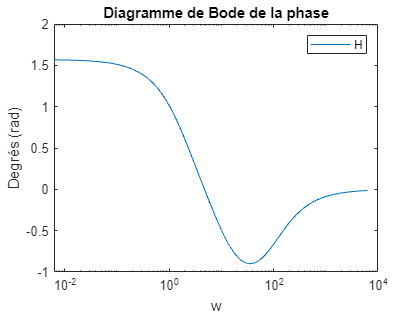


figure('name', 'Diagramme de Bode de la phase');
semilogx(w, phase);
title('Diagramme de Bode de la phase');
xlabel('w');
ylabel('Degrés (rad)');
legend('H');

num = [20 2000 0];

num =           20        2000           0


den = [1 12 20];

den =      1    12    20


H = tf(num,den);

H =
 
  20 s^2 + 2000 s
  ---------------
  s^2 + 12 s + 20
 
Continuous-time transfer function.



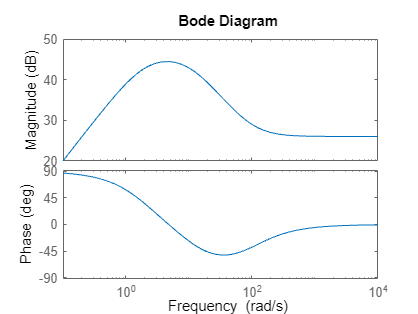

bode(H);